Load data from home page

load("A_Homepage.mat")

Prepare the parameters

Convert delay to amount of samples

delaysamples = round(fs*delay/1000);

Apply the slope to the range control

range = ceil(range*10.1010);

Interpolate data

interpol_factor = 2;
audio = interp1(1 : length(audio), audio, 1 : 1/interpol_factor : length(audio));
audio = audio';
fs = fs*interpol_factor;
range = range*interpol_factor;
delaysamples = delaysamples*interpol_factor;

Preallocate arrays for the output, dry, and wet signals

output = zeros(1, length(audio)-delaysamples-range);
dry = zeros(1, length(audio)-delaysamples-range);
wet = zeros(1, length(audio)-delaysamples-range);

Generate the output signal

for i = 1 : length(audio)-delaysamples-range    

Generate the dry signal as the input signal

    dry(i) = audio(i);

Calculate the index with the applied delay

    delay = i + delaysamples;

Calculate the phase shift with the time varying delay

    sweep = range*sin(2*pi*(sweep_freq/fs)*i);

Array indices must be integers. Round the 'sweep' variable in case if not integer

    sweep = ceil(sweep);

Calculate the total delay index

    delay_index = delay + sweep;

Generate the wet signal as the delayed and time-varying phase shifted input

    wet(i) = audio(delay_index);

Generate the output as the sum of the dry and wet signal

    output(i) = (1-mix_p)*dry(i) + mix_p*wet(i);
end

Downsample the input and output data

audio = downsample(audio, interpol_factor);
output = downsample(output, interpol_factor);
fs = fs/interpol_factor;

Save output to a .mat file.

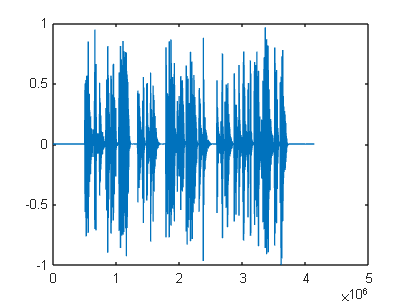

save("effectoutput.mat", "output", "fs", "effect", ...
    "WriteNewFile", "PlayAudio")
clear